## Assignment 5 - EMG and Muscular Force Analysis

## **Assignment Description**

**Learning outcome** After this assignment student can • characterize the level of activity in EMG signals, and • analyze the relationship between EMG signal properties and muscular force.

**Required reading** Read chapter 5 from the course book.

**Assignment description** In this lab assignment, you will explore several measures, features, properties, or in other words parameters derived from EMG signals, and study their relationship to the associated muscular force.

Note: This lab exercise is based on the material provided in [http://people.ucalgary.ca/~ranga/](http://people.ucalgary.ca/~ranga/). The material is used with the permission of Professor Rangaraj M. Rangayyan.

## **Problem Summary**

### Introduction

EMG signal is the electrical signal associated with muscular contraction. Level of activity of the EMG signal increases with force; see Section 1.2.4 of the course book for details on the EMG signal.

In order to investigate the relationship between an independent variable and a dependent variable, it is common practice to fit a mathematical function or a curve to the data samples available, and then to examine the accuracy of the underlying model (goodness of fit). In the present lab assignment, you will investigate the appropriateness of linear fits (straight-line or linear models) to represent the variation of each of the parameters DR, MS, ZCR and TCR as a function of independent variable force.

**A brief explanation of the parameters:**

- The dynamic range (DR) of a signal is the difference between its maximum and minimum values over a specified duration. This range of values is also referred to as the peak-to-peak swing or range.

- The average power of a signal is provided by the mean-squared (MS) value over a specified duration of time; the average magnitude over the same duration is given by the root-mean-squared (RMS) value. With the mean of the EMG signal being zero, the RMS value is equal to the standard deviation of the signal.

- An approximate indicator of the level of activity in a signal is given by the number of times the signal crosses the zero line (assuming a mean value of zero; if the mean is not zero, it should be subtracted from the signal). A zero crossing is said to occur when the sign of a sample of the signal is different from the sign of the preceding sample. The average number of zero crossings over a certain time period is known as the zero-crossing rate (ZCR). It is expected that increased presence of high-frequency components in a signal will lead to larger ZCR. See Section 5.6 on statistical analysis of EMG signals. 

- Turns count (TC) is the number of times the signal amplitude changes direction. In Willison method (used in this assignment) turns greater than 100 µV are counted, with the threshold selected to avoid counting insignificant fluctuations due to noise. TCR (Turns Count Rate) is the turns count divided by the time duration of the segment.

### Data

Muscle force and EMG data from the original experiment are shown in Figure 1. The sampling rate is 2000 Hz for all provided signals, and the EMG sample values are in mV. The data segments have been prepared for the assignment and are available in `data.mat` file. The segments were cropped at their 70% of maximal value within the segment. The `data` variable is a `1x5 struct` (for the 5 segments), and has the following fields:

- `t`: the time points for the segment

- `force`: muscle force data readily prepared in percent of maximal voluntary contraction

- `EMG`: the EMG data for the segment with its mean (DC) subtracted

- `length`: the number of samples in the segment

You can reach the data with the following syntax: for example `data(2).force` is the force signal from the second segment, `data(5).EMG` is the EMG signal of the fifth segment, and so on.

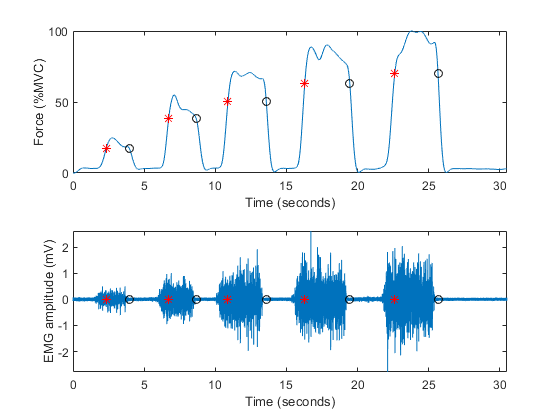

**Figure 1. *****Muscle force and EMG signals of the experiment with segment starting and ending points marked with red stars and black circles, respectively. %MVC: percent of maximal voluntary contraction***

**Useful MATLAB commands: **

`hold, max, min, diff, sign, abs, polyfit``, ``polyval``, ``find`

### `Task`

Your task is to:

- Study the data by plotting it with respect to time. I.e. plot all the segments of the already normalized force (in %MVC) in a `subplot``(2,1,1)`, and the EMG signal (in mV) in a `subplot``(2,1,2)` against their time corresponding time axes. Your plot will be like Figure 1 above, with the discarded signal parts (not belonging to any segment) missing from the plot. Hint: you can plot the 5 segments with separate plot signals (using `hold on`), and keep the segments in their default colors.

- Calculate the average force exerted within each segment of the force signal.

- Compute the DR for each segment of the EMG signal. 

- For each segment of the EMG signal, compute MS. Ensure that the MS values are computed using the appropriate number of samples for each segment. The MS value of a signal `x` over its duration of `N` samples is the following: MS=1NN−1i=0x2(i).

- For each segment of the EMG signal, compute ZCR **without** using `dsp.ZeroCrossingDetector`. Ensure that you normalize ZCR to zero crossings per second by dividing the number of zero crossings by the time duration of the corresponding segment. Do not remove the mean but assume the signal is zero mean already.

- For each segment of the EMG signal, compute TCR with the algorithm***** given below.

- Using the `polyfit` and `polyval` functions in MATLAB, obtain a straight-line (linear) fit to represent the variation of each EMG parameter as a function of independent variable force. Superimpose the obtained linear models (straight-line fits) on their corresponding subplots of the preceding step.

- Compute the correlation coefficients (`r`) for each parameter with `corr` function.

***) TCR algorithm**

To find the TCR, proceed as follows:

- Compute the derivative of the EMG signal (`diff`)

- Detect the points of change in its sign (defined as the MATLAB `sign` function, taking values in {-1, 0, 1})

- A significant turn is found wherever the derivative signal changes sign, and the original signal differs by at least 100 μV between current and previous (significant or non-significant) turn points (not the previous samples).

- TCR is the amount of significant turns divided by the time duration of the corresponding segment

Note 1: A sign change between two of the derivative samples implies that there exists a zero crossing between them (as the derivative is considered also to be a continuous signal). This vanishing of the derivative happens at an extrema point (min/max) of the original signal.

Note 2: If utilizing the MATLAB `sign` command, please also consider that it evaluates to 0 at 0.


% The sampling rate is 2000 Hz 
FS = 2000;

% Load the signals from data.mat into the struct 'data'
load("data.mat");

% Number of segments
N = numel(data);

% Calculate average force of each segment (1xN vector)
AF = arrayfun(@(x) mean(x.force),data)

AF =    21.0678   46.1423   67.5875   82.8566   92.5053



% Calculate EMG dynamic range in each segment (1xN vector)
DR = arrayfun(@(x) range(x.EMG),data)

DR =     1.0970    1.9510    3.8950    4.5630    4.1850



% Calculate EMG mean squared value in each segment (1xN vector)
MS = arrayfun(@(x) meansqr(x.EMG),data)

MS =     0.0187    0.0710    0.1916    0.2196    0.2924



% Calculate EMG zero crossing rate in each segment (1xN vector)
ZCR = arrayfun(@(x) ZeroCrossingRate(x.EMG, FS),data)

ZCR =   131.1475  149.2383  150.3062  167.6685  156.5275



% Calculate EMG turns rate in each segment (1xN vector)
TCR = arrayfun(@(x) TurnsCountRate(x.EMG, FS),data)

turn_idx =     11
    12
    15
    17
    20
    33
    37
    41
    49
    51


sgnf_turns = 950×1 logical array
   0
   0
   0
   0
   1
   1
   1
   1
   0
   0


turn_idx =      3
     7
    16
    19
    23
    26
    27
    28
    30
    34


sgnf_turns = 968×1 logical array
   0
   1
   1
   1
   1
   0
   0
   0
   1
   0


turn_idx =      6
     8
    10
    13
    14
    20
    27
    31
    35
    38


sgnf_turns = 1344×1 logical array
   0
   0
   1
   0
   1
   1
   1
   1
   0
   0


turn_idx =      9
    22
    27
    29
    36
    46
    54
    55
    56
    57


sgnf_turns = 1556×1 logical array
   1
   1
   1
   1
   1
   1
   0
   0
   0
   1


turn_idx =     10
    22
    23
    24
    30
    41
    46
    48
    51
    58


sgnf_turns = 1443×1 logical array
   1
   0
   0
   1
   1
   1
   0
   0
   1
   1


TCR =   114.4448  204.4926  250.1392  288.1999  284.4459


% Calculate the linear model coefficients for each parameter
% The models are in the form: parameter(force) = constant + slope * force,
% and the coefficients are stored in a 1x2 vectors: p_<param> = [slope constant]
% For example, p_DR(1) is the slope and p_DR(2) is the constant of the linear model mapping the average force into the dynamic range
% You can use the 'polyfit' (or the 'regress') command(s) to find the model coefficients
p_DR = polyfit(AF', DR', 1)

p_DR =     0.0506   -0.0020


p_MS = polyfit(AF', MS', 1)

p_MS =     0.0038   -0.0776


p_ZCR = polyfit(AF', ZCR', 1)

p_ZCR =     0.4071  125.7271


p_TCR = polyfit(AF', TCR', 1)

p_TCR =    -1.3689  595.9668


% Calculate correlation coefficients between the average forces and each of the parameters using 'corr'
c_DR = corr(AF', DR')

c_DR = 0.9583

c_MS = corr(AF', MS')

c_MS = 0.9820

c_ZCR = corr(AF', ZCR')

c_ZCR = 0.8831

c_TCR = corr(AF', TCR')

c_TCR = 0.9781

ans =     1.0645    2.3338    3.4194    4.1924    4.6809


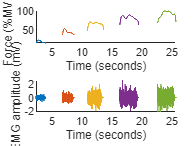

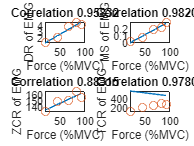

visualize_all(data, AF, DR, MS, ZCR, TCR, p_DR, p_MS, p_ZCR, p_TCR, c_DR, c_MS, c_ZCR, c_TCR)

% For old matlab
% function msqr = meansqr(X)
%     msqr = sum(power(X, 2))/length(X);
% end

function zcr = ZeroCrossingRate(X, FS)
    n = length(X);
    t = n / FS;
    crossings = abs(diff(sign(X)));
    crossing_count = sum(crossings == 2);
    zcr = crossing_count / t;
end

function tcr = TurnsCountRate(X, FS)
    n = length(X);
    t = n / FS;
    Y = sign(diff(X));
    mult_cond = Y(1:n-2) .* Y(2:n-1);

    turn_idx = find(mult_cond <= 0) + 1;
    sgnf_turns = abs(diff(X(turn_idx))) >= 0.1;
    tcr = sum(sgnf_turns) / t;
end